# Three Node Network inversion with TAPAS

## Simulate resting state data for three node network

As done in Frässle et al. (2021) using `DEM_demo_induced_fMRI.m `to generate resting state time series.

T  = 512;                             % number of observations (scans)
TR = 2;                               % repetition time or timing
t  = (1:T)*TR;                        % observation times
n  = 3;                               % number of regions or nodes
u  = spm_rand_mar(T,n,1/2)/4;         % endogenous fluctuations

% experimental inputs (Cu = 0 to suppress)
% -------------------------------------------------------------------------
Cu  = [1; 0; 0] * 0;
E   = cos(2*pi*TR*(1:T)/24) * 0;

% priors
% -------------------------------------------------------------------------
options.nonlinear  = 0;
options.two_state  = 0;
options.stochastic = 1;
options.centre     = 1;
options.induced    = 1;

A   = ones(n,n);
B   = zeros(n,n,0);
C   = zeros(n,n);
D   = zeros(n,n,0);
pP  = spm_dcm_fmri_priors(A,B,C,D,options);

% true parameters (reciprocal connectivity)
% -------------------------------------------------------------------------
% pP.A = [  0  -.2    0;
%          .3    0  -.1;
%           0   .2    0];
pP.A =[0 0.2 0;
    0.4 0 0;
    0 0.3 0];
pP.C = eye(n,n);
pP.transit = randn(n,1)/16;

% simulate response to endogenous fluctuations
%==========================================================================

% integrate states
% -------------------------------------------------------------------------
M.f  = 'spm_fx_fmri';
M.x  = sparse(n,5);
U.u  = u + (Cu*E)';
U.dt = TR;
x    = spm_int_J(pP,M,U);

% haemodynamic observer
% -------------------------------------------------------------------------
for i = 1:T
    y(i,:) = spm_gx_fmri(spm_unvec(x(i,:),M.x),[],pP)';
end

% observation noise process
% -------------------------------------------------------------------------
e    = spm_rand_mar(T,n,1/2)/4;


% nonlinear system identification (DCM for CSD)
%==========================================================================
DCM.options = options;

% DCM.a    = logical(pP.A);
DCM.a = ones(n, n);
DCM.b    = zeros(n,n,0);
DCM.c    = logical(Cu);
DCM.d    = zeros(n,n,0);

% response
% -------------------------------------------------------------------------
DCM.Y.y  = y + e;
DCM.Y.dt = TR;
DCM.U.u  = E';
DCM.U.dt = TR;

Visualize simulated BOLD data.

names = {'1' '2' '3'};
tmp = digraph(pP.A', names);

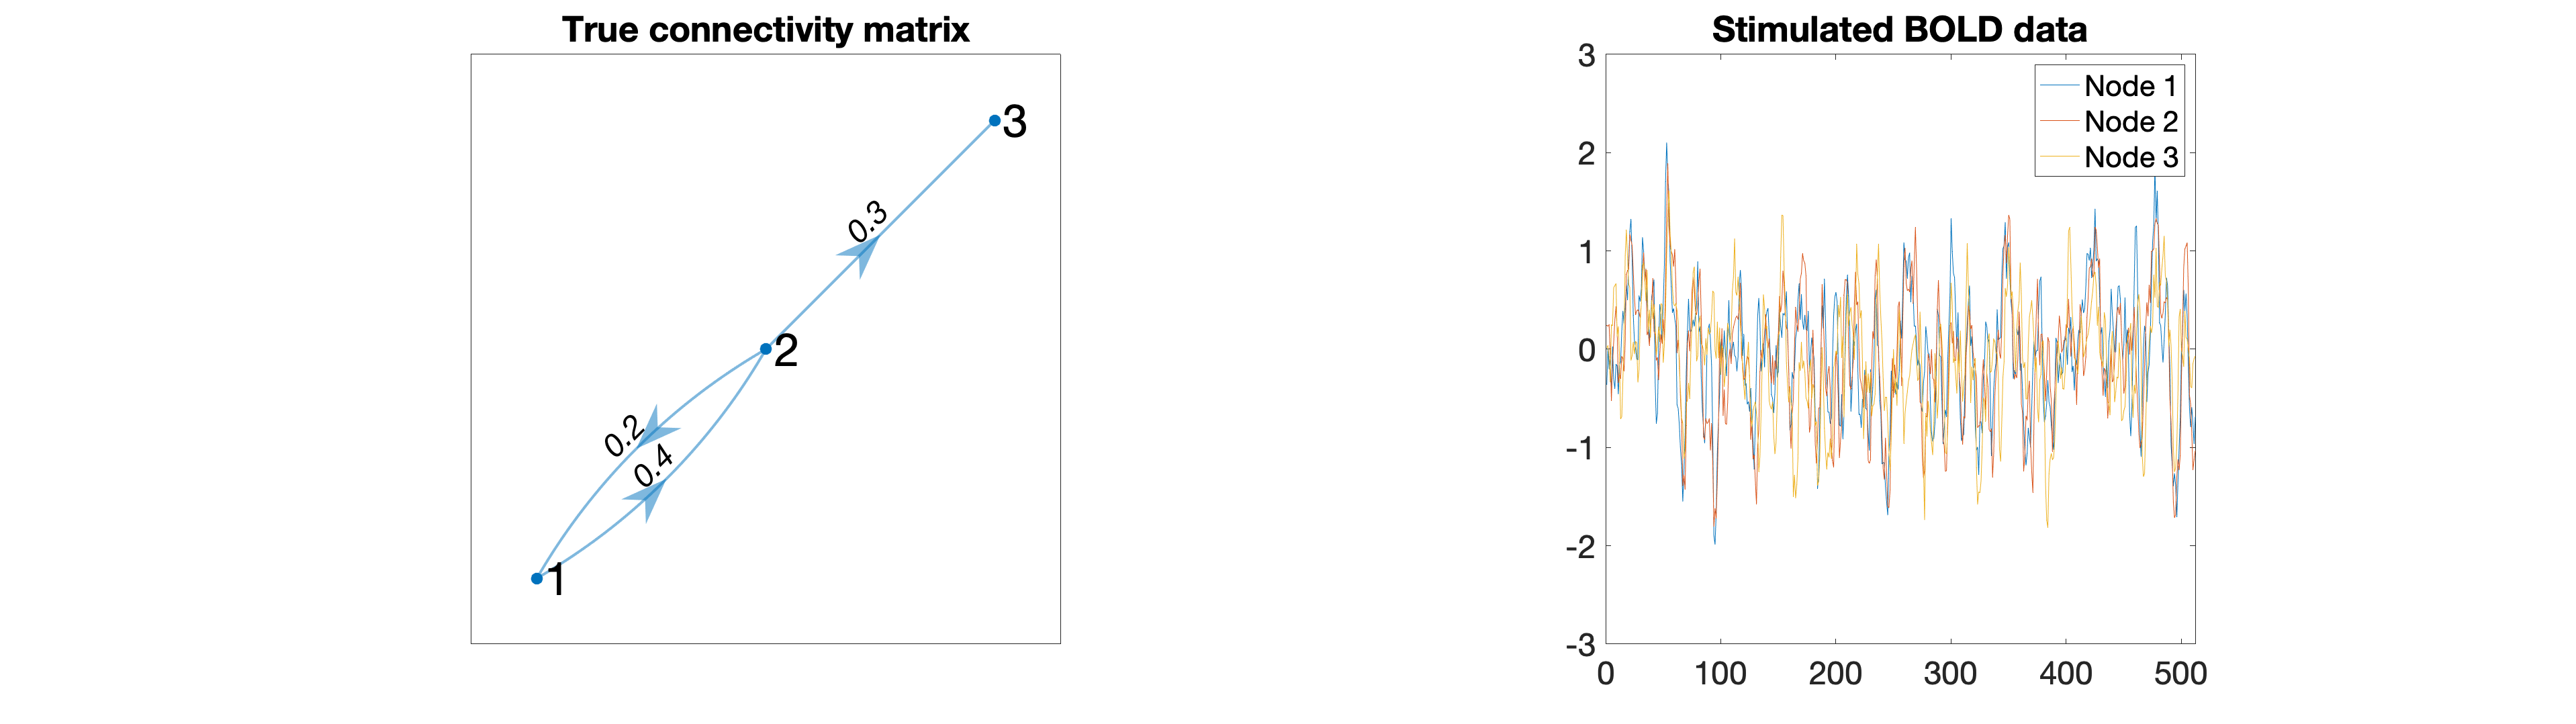

clf
subplot(1, 2, 1)
p = plot(tmp,'Layout','force','EdgeLabel',tmp.Edges.Weight);
title("True connectivity matrix")
axis square
ax = gca;
ax.FontSize = 24;
p.LineWidth = 2;
p.NodeFontSize = 34;
p.EdgeFontSize = 24;
p.ArrowSize = 26;
highlight(p,[1 2 3]);

subplot(1,2,2)
plot(DCM.Y.y);
axis([0 512 -3 3])
title("Stimulated BOLD data");
legend("Node 1", "Node 2", "Node 3")
axis square
ax = gca;
ax.FontSize = 24;

set(gcf,'position',[0,0,400,250]);
set(gcf,'Units','normalized','Position',[0 0 1 .5]); 

Specify the options for the rDCM analysis

% options.SNR             = 3;
% options.y_dt            = 0.5;
% options.p0_all          = 0.15;  % single p0 value (for computational efficiency)
% options.iter            = 100;
% options.filter_str      = 5;
% options.restrictInputs  = 1;
%
% % run a simulation (synthetic) analysis
type = 's';

## Invert simulated data

% method = 2;
% [output, options] = tapas_rdcm_estimate(DCM, type, options, method);

Why is `tapas_rdcm_generate.m` convolving signal using the loop below?

They convolve the neural signal with the HRF in frequency space and then ifft to convert back into time space.

**But why do they then only take the middle chunk of the signal tripled in length?**

% for i = 1:nr
%     tmp = ifft(fft(x(:,i)).*fft([h; zeros(N*3-length(h),1)]));
%     y(:,i) = tmp(N+1:2*N);
% end